# Tunnel Characteruzation - Pitot Probe

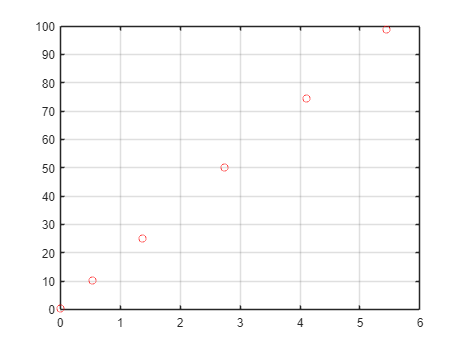

% Take ascending pressure points starting at ~0.3 kPa and plot

pitot_cal_P = [0.4 10.18 25.04 49.90 74.50 98.63]; % Para Scientific readout (kPa)

pitot_cal_V = [0 0.543 1.365 2.742 4.105 5.444]; % Voltage readout (KSC-2 balanced at -2.6465 mV)

plot(pitot_cal_V, pitot_cal_P,'ro')
grid on

% Use best fit techniques to create calibration curve from collected data

% Cal1 = table2array(Cal1);
% Cal2 = table2array(Cal2);
% Cal3 = table2array(Cal3);
% Cal4 = table2array(Cal4);
% Cal5 = table2array(Cal5);
% Cal6 = table2array(Cal6);
% Cal7 = table2array(Cal7);

% Take drvier tube calibration from Campaign 1 or 3 analysis

DCal1 = table2array(DCal1);
DCal2 = table2array(DCal2);
DCal3 = table2array(DCal3);
DCal4 = table2array(DCal4);
DCal5 = table2array(DCal5);

% This section plots Driver tube and Kulite calibration curves as well as
% calculates the calibration coefficients needed in later sections

% DCal data
DCal_points = [sum(DCal1)./(height(DCal1)), sum(DCal2)./(height(DCal2)), sum(DCal3)./(height(DCal3)), sum(DCal4)./(height(DCal4)), sum(DCal5)./(height(DCal5))];
DCal_pressures = [71.9 91.0 110.8 130.1 150.2];

% Calibration Curve
DCal_fit_coeffs = polyfit(DCal_pressures, DCal_points, 1);
DCal_fit = polyval(DCal_fit_coeffs, DCal_pressures);

% Plot DCal data and best-fit line
figure;
plot(DCal_points, DCal_pressures, 'ko', 'DisplayName', 'Data');
hold on
plot(DCal_fit, DCal_pressures, 'b-', 'DisplayName', 'Best Fit Line');
grid on
hold off
legend('Location', 'northwest')
ylabel('Pressure (psi)');
xlabel('Voltage Read-outs (V)');
title('Driver Tube Calibration Curve');


% For KCal data
KCal_points = [sum(KCal1)./(height(KCal1)), sum(KCal2)./(height(KCal2)), sum(KCal3)./(height(KCal3)), sum(KCal4)./(height(KCal4)), sum(KCal5)./(height(KCal5)), sum(KCal6)./(height(KCal6)), sum(KCal7)./(height(KCal7))];
KCal_pressures = [35.65 22.38 18.18 14.55 10.09 5.80 4.80];

% Find best-fit line for KCal data
KCal_fit_coeffs = polyfit(KCal_pressures, KCal_points, 1);
KCal_fit = polyval(KCal_fit_coeffs, KCal_pressures);

% Plot KCal data and best-fit line
figure;
plot(KCal_pressures, KCal_points, 'ro', 'DisplayName', 'Data');
hold on
plot(KCal_pressures, KCal_fit, 'k-', 'DisplayName', 'Best Fit Line');
grid on
hold off
legend('Location', 'northwest')
xlabel('Pressure (kPa)');
ylabel('Voltage Read-outs (V)');
title('Test Section Calibration Curve');

% Average Mach number calculation

% Mach number during steady-state run time 
Tstart = 0.55; % time elapsed where steady state begins (sec)
Tend = 1.9; % time elapsed where steady state ends (sec)

% Find Mean of steady-state run time stagnation pressure, Po2 just passed Normal Shock

Po2 = mean(Pitot_([(250000 * (Tstart + 0.2)) (250000 * (Tend + 0.2))])) % (kPa)

% Find Mean of corresponding Driver Tube pressure, Po1, convert to kPa

Po1 = 6.89476 * mean(Pitot_DT_([(250000 * (Tstart + 0.2)) (250000 * (Tend + 0.2))])) % (kPa)

% Find Po2 / Po1

Avg_Po2_Po1 = Po2 / Po1

% Solve for Upstream Mach Number using Po2/Po1 via Normal Shock Relations
% Note: simplified for gamma = 1.4

NormalShockRelation = @(M) ((2.4 * M^2) / (0.4 * M^2 + 2))^3.5 * ...
    (2.4 / (2.8 * M^2 - 0.4))^2.5 - Avg_Po2_Po1;

Avg_Minf = fzero(NormalShockRelation, [1,7]) % [1,7] being the range of guesses


% Determine Tunnel noise via pressure trace deviation from mean

Tstart = 0.5; % time elapsed where steady state begins (sec)
Tend = 1.1; % time elapsed where steady state ends (sec)

Pressmean = mean(Press_KRun1([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))])) % (kPa)

Pressmean = 17.1294


deviation = std(Press_KRun1([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))])) % (kPa)

deviation = 0.5772


Meanremoved = Press_KRun1 - Pressmean;

rootms_withmean = rms(Press_KRun1([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))]), 1) % (kPa)

rootms_withmean = 17.1391


rootms_removed = rms(Meanremoved([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))]), 1) % (kPa)

rootms_removed = 0.5772


noise = 100 * (rootms_removed / Pressmean) % Percent noise level

noise = 3.3699